# SDR

Generate IOT signals

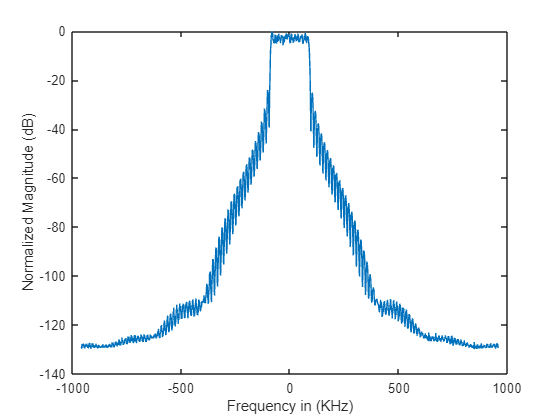

n_devices = 6;

[waveform,Fs] = Generate_NBiot();
[signal,f] = pwelch(waveform,2048,1024,2048,Fs);
signal = fftshift(signal/max(abs(signal)));
figure;
F= f - f(length(f)/2+1);
plot(F/1e3,20*log10(signal))
xlabel('Frequency in (KHz)')
ylabel('Normalized Magnitude (dB)')

B = 200e3*7;
Fs_up = 2*B;
up_factor = ceil(Fs_up/Fs);
upsampled_sig = upsample(signal,up_factor);

F(1)-F(2)

ans = -937.5000

F(end)-F(end-1)

ans = 937.5000

LPF to remove the simulated noise produced in the electorics of the sensors and to increase the fs/2 to make the DUC possible

filtered_upsampled_sig = filter(TX_filter,upsampled_sig);
F_new = linspace(2*F(2),2*F(end)+1,length(filtered_upsampled_sig));
F_new = 2*F(1): 937.5:2*F(end)+937.5;
hold on;
plot(F_new/1e3,(20*log10(filtered_upsampled_sig)))

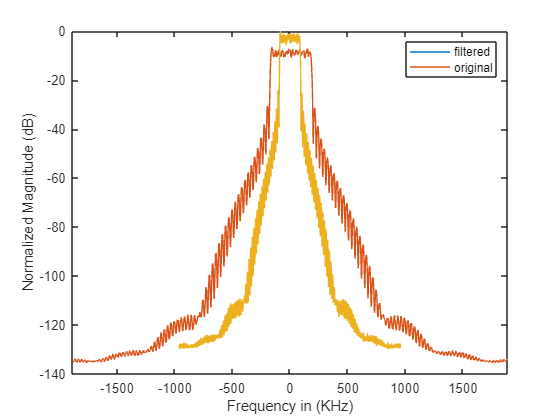

plot(F/1e3,20*log10(signal))
xlabel('Frequency in (KHz)')
ylabel('Normalized Magnitude (dB)')
xlim([-1885 1885])
legend('filtered','original')
hold off;

filtered_upsampled_sig = filter(TX_filter_complex_flat_top,upsampled_sig);
F_new = linspace(2*F(2),2*F(end)+1,length(filtered_upsampled_sig));
F_new = 2*F(1): 937.5:2*F(end)+937.5;
figure;
hold on;
plot(F_new/1e3,(20*log10(filtered_upsampled_sig)))

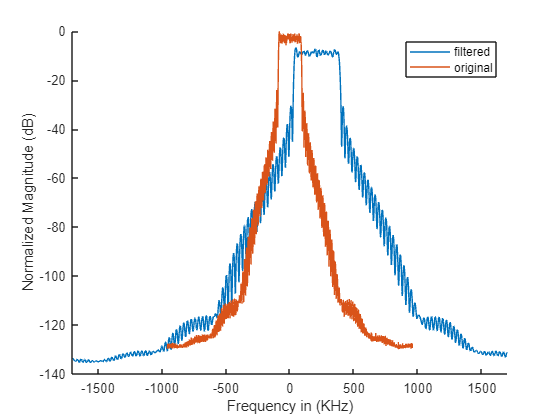

plot(F/1e3,20*log10(signal))
xlabel('Frequency in (KHz)')
ylabel('Normalized Magnitude (dB)')
xlim([-1700 1700])
legend('filtered','original')
hold off;